% Fisrt part - Curve fitting. First polynomyial.
clc, clear ,close all;
a0 = -2.923;
b0 = 7.18;
sigma = 3.8;
mu = 0;
N = 100;
x = 50.*rand(100,1);
y = ones(100,1);
e =  sigma.*randn(100,1);

for i=1:N
    y(i) = a0 + b0*x(i)+e(i);
end
% 
scatter(x, y,".");
hold on;
grid on;
title('Random Scatter Plot');
xlabel('X-axis');
ylabel('Y-axis');
Big_phi_a  = ones(100,2);

for i = 1:N
    Big_phi_a(i,:) = [1 x(i)];
end

theta_hat_a = (transpose(Big_phi_a)*Big_phi_a)\(transpose(Big_phi_a)*y)

theta_hat_a =    -2.3772
    7.1407


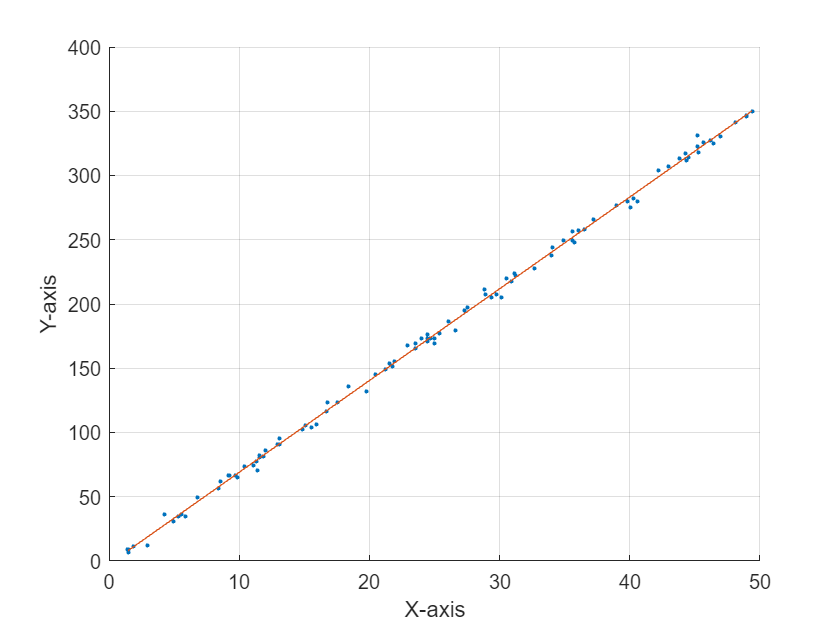


y_predited_a  = transpose(theta_hat_a)*transpose(Big_phi_a);
plot(x, y_predited_a);
title("");
xlabel('X-axis');
ylabel('Y-axis');

% The mean squared error in prediction.
MSE = mean(y.^2-transpose(y_predited_a).^2)

MSE = 13.6542

% Fit a 2nd order polynomial 
clc, clear ,close all;
a0 = -2.923;
b0 = 7.18;
c0 = 2.8;

sigma = 12.8;
mu = 0;
N = 100;
x = 50.*rand(100,1);
y = ones(100,1);
e = normrnd(mu, sigma, [N, 1]);

for i=1:N
    y(i) = a0 + b0*x(i) + c0*x(i)^2+e(i);
end

scatter(x, y,".");
hold on;
grid on;
title('Random Scatter Plot');
xlabel('X-axis');
ylabel('Y-axis');

Big_phi_b = ones(100,3);
for i = 1:N
    Big_phi_b(i,:) = [1 x(i) x(i)^2];
end

% Theta for poly2
theta_hat_b = (transpose(Big_phi_b)*Big_phi_b)\(transpose(Big_phi_b)*y)

theta_hat_b =    -5.6056
    7.4998
    2.7932



y_predcited_b  = transpose(theta_hat_b)*transpose(Big_phi_b);

% Theta for poly1
FirstPolyF = fit(x,transpose(y_predcited_b),"poly1");
SecindP = fit(x,transpose(y_predcited_b),"poly2");

coefficients_first_poly = coeffvalues(FirstPolyF);

firstPolyY = zeros(100,1);
secondPolyY = zeros(100,1);
for i = 1:100
    firstPolyY(i) = coefficients_first_poly(1) * x(i) + coefficients_first_poly(2);
    secondPolyY(i) = theta_hat_b(1) * x(i)^2 + theta_hat_b(2) * x(i) + theta_hat_b(3);
end

error_first_poly = mean(y.^2-firstPolyY.^2)

error_first_poly = 2.1425e+05

error_second_poly = mean(y.^2-transpose(y_predcited_b).^2)

error_second_poly = 152.8547

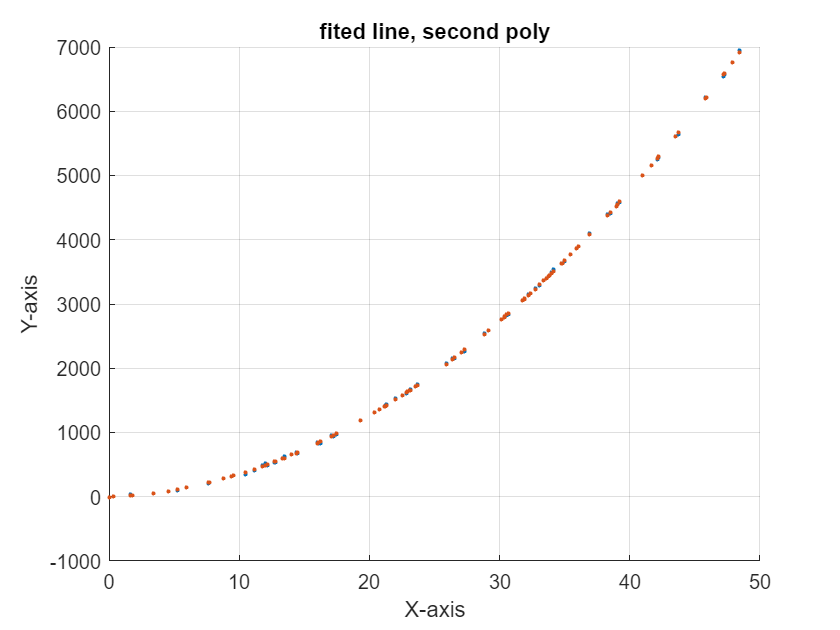


scatter(x,y_predcited_b,".");
title("fited line, second poly");
xlabel('X-axis');
ylabel('Y-axis'); hold off;

LMS = rms(e)

LMS = 12.4154


error_first_poly / error_second_poly

ans = 1.4016e+03

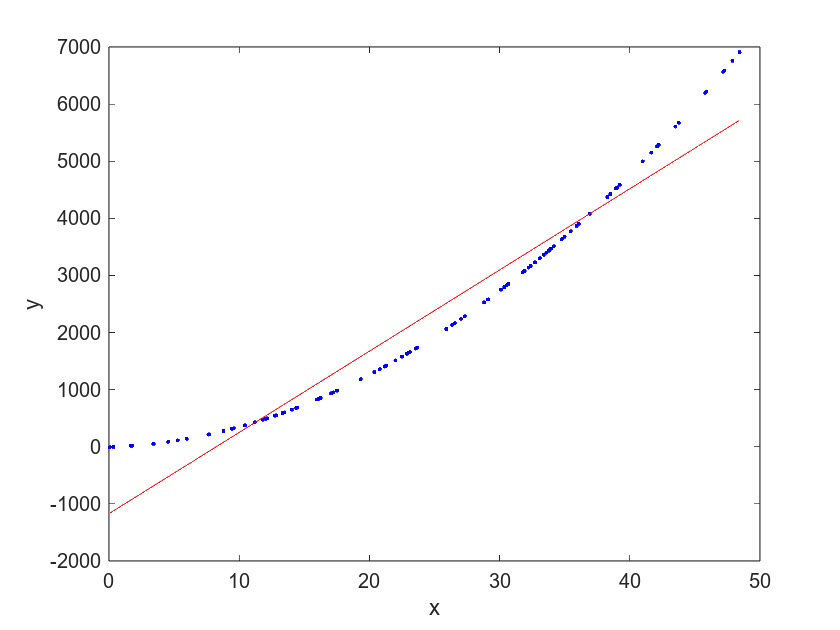

plot(FirstPolyF, x,y_predcited_b)


% Commnet: We can see that the error between the first polynomial fit line
% is larger than the second line, therefore we can see that the second
% polynomial line is better fitted for this 



clc, clear ,close all;

input_data = importdata("input.mat");
output_data = importdata("output.mat");


number_of_elements = length(input_data);

x_train = input_data(1:0.7*number_of_elements,:);
y_train = output_data(1:0.7*number_of_elements,:);


x_test = input_data(0.7*number_of_elements:number_of_elements,:);
y_test = output_data(0.7*number_of_elements:number_of_elements,:);



% ------------------12_a equation----------------------
% -------------------------a---------------------------
PHI_12a = zeros(3,length(y_train));
PHI_12a(:,1) = [x_train(1) 0 0];
PHI_12a(:,2) = [x_train(2) y_train(1) 0];

for i = 3:length(y_train)
    PHI_12a(:,i) = [x_train(i) y_train(i-1) y_train(i-2)];
end
Theta_12a = (PHI_12a*transpose(PHI_12a))\PHI_12a*y_train

Theta_12a =     0.0351
    0.9291
   -0.3391



% -------------------------b---------------------------

b0 = Theta_12a(1);
a1 = Theta_12a(2);
a2 = Theta_12a(3);

y_pred_12a = zeros(length(y_test),1);
y_sim_12a = zeros(length(y_test),1);

y_pred_12a(1) = x_test(1)*b0 + 0 + 0;
y_pred_12a(2) = x_test(2)*b0 + y_test(1)*a1 + 0;

y_sim_12a(1) = x_test(1)*b0 + 0 + 0;
y_sim_12a(2) = x_test(2)*b0 + y_sim_12a(1)*a1+ 0;

for i = 3:length(y_test)

y_pred_12a(i) = x_test(i)*b0 +  y_test(i-1)*a1 + y_test(i-2)*a2; % testing the data
y_sim_12a(i) = x_test(i)*b0 + y_sim_12a(i-1)*a1 + y_sim_12a(i-2)*a2; % create new data with the predicted paramiters

end

% 
% scatter(x_test,y_pred_12a,"red")
% grid on 
% hold on 
% scatter(x_test,y_sim_12a,"yellow")

error_in_pred = rmse(y_test,y_pred_12a)

error_in_pred = 1.0355


error_in_sim = rmse(y_test,y_sim_12a)

error_in_sim = 1.4060




% ------------------12_b equation----------------------
% -------------------------a---------------------------
PHI_12b = zeros(4, length(y_train));

PHI_12b(:,1) = [x_train(1) 0 0 0];
PHI_12b(:,2) = [x_train(2) x_train(1) -y_train(1) 0];

for i = 3:length(y_train)
    PHI_12b(:,i) = [x_train(i) x_train(i-1) -y_train(i-1) -y_train(i-2)];
end

Theta_12b = (PHI_12b*transpose(PHI_12b))\PHI_12b*y_train

Theta_12b =     0.0038
    1.0005
   -0.8981
    0.3211


% -------------------------b---------------------------

y_pred_12b = zeros(length(y_test),1);
y_sim_12b = zeros(length(y_test),1);

y_pred_12b(1,:) = transpose(Theta_12b) * [x_test(1); 0; 0; 0];
y_pred_12b(2,:) = transpose(Theta_12b) * [x_test(2); x_test(1); -y_test(1); 0];


y_sim_12b(1,:) = transpose(Theta_12b) * [x_test(1); 0; 0; 0];
y_sim_12b(2,:) = transpose(Theta_12b) * [x_test(2); x_test(1); -y_sim_12b(1); 0];

for i = 3:length(y_test)

y_pred_12b(i,:) = transpose(Theta_12b) * [x_test(i); x_test(i-1); -y_test(i-1); -y_test(i-2)];
y_sim_12b(i,:) = transpose(Theta_12b) * [x_test(i); x_test(i-1); -y_sim_12b(i-1); -y_sim_12b(i-2)];
end

% scatter(x_test,y_pred_12b,"red")
% grid on 
% hold on 
% scatter(x_test,y_sim_12b,"yellow")
% scatter(x_test,y_test,"green")

error_in_pred = rmse(y_test ,y_pred_12b)

error_in_pred = 0.3099


error_in_sim = rmse(y_test,y_sim_12b)

error_in_sim = 0.4208


% ------------------12_c equation----------------------
% -------------------------a---------------------------
PHI_12c = zeros(4, length(y_train));

PHI_12c(:,1) = [0 0 0 0];
PHI_12c(:,2) = [x_train(1) -y_train(1) 0 0];
PHI_12c(:,3) = [x_train(2) -y_train(2) -y_train(1) 0];
for i = 4:length(y_train)
    PHI_12c(:,i) = [x_train(i-1) -y_train(i-1) -y_train(i-2) -y_train(i-3)];
end

Theta_12c = (PHI_12c*transpose(PHI_12c))\PHI_12c*y_train

Theta_12c =     1.0000
   -1.0000
    0.6000
   -0.3000


% -------------------------b---------------------------


y_pred_12c = zeros(length(y_test),1);
y_sim_12c = zeros(length(y_test),1);

y_pred_12c(1) = transpose(Theta_12c) * [0; 0; 0; 0];
y_pred_12c(2) = transpose(Theta_12c) * [x_test(1); -y_test(1); 0; 0];
y_pred_12c(3) = transpose(Theta_12c) * [x_test(2); -y_test(2); -y_test(1) ;0];



y_sim_12c(1) = transpose(Theta_12c) * [0; 0; 0; 0];
y_sim_12c(2) = transpose(Theta_12c) * [x_test(1); -y_sim_12c(1); 0; 0];
y_sim_12c(3) = transpose(Theta_12c) * [x_test(2); -y_sim_12c(2); -y_sim_12c(1); 0];


for i = 4:length(y_test)
y_pred_12c(i) = transpose(Theta_12c) * [x_test(i-1); -y_test(i-1); -y_test(i-2) ; -y_test(i-3)];
y_sim_12c(i) = transpose(Theta_12c) * [x_test(i-1); -y_sim_12c(i-1); -y_sim_12c(i-2) ; -y_sim_12c(i-3)];
end

error_in_pred = rmse(y_test ,y_pred_12c)

error_in_pred = 0.0093

error_in_sim = rmse(y_test ,y_sim_12c)

error_in_sim = 0.0143

The best models in prediction and simulation are the thierd candidate because the root squared mean error are minimum. 